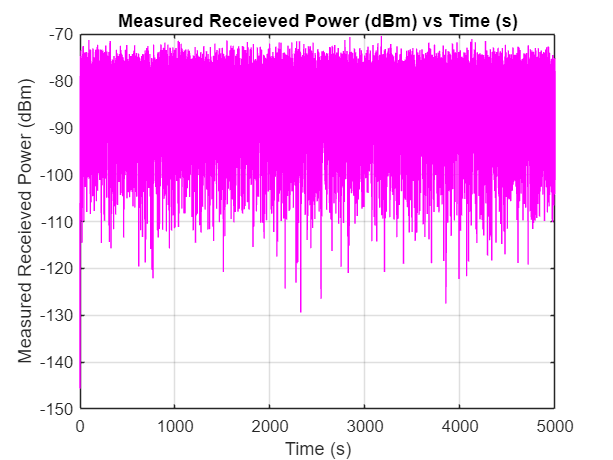

% Step 1

% Clear Everything
clear;

% Load Series11 Into A Vector
data = load("series11.mat");

% Grab Time and Power
time = data.series11(:,1);
power_dbm = data.series11(:,2);

% Plot Power vs Time
figure;
plot(time, power_dbm, Color = 'm');
xlabel('Time (s)');
ylabel('Measured Receieved Power (dBm)');
title('Measured Receieved Power (dBm) vs Time (s)');
grid on;

% Step 2

% Calculate Voltage Vector
R = 50;
power_w = 10.^(power_dbm/10) * 1e-3;
V = sqrt(2*R*power_w);

% Find Mean Of Voltage Vector
V_avg = mean(V);

% Sigma Parameter
sigma = V_avg / sqrt(pi/2);

% Display Values
disp(['Mean Of Voltage Vector: ', num2str(V_avg)]);

Mean Of Voltage Vector: 2.6619e-05


disp(['Sigma Paramter: ', num2str(sigma)]);

Sigma Paramter: 2.1239e-05


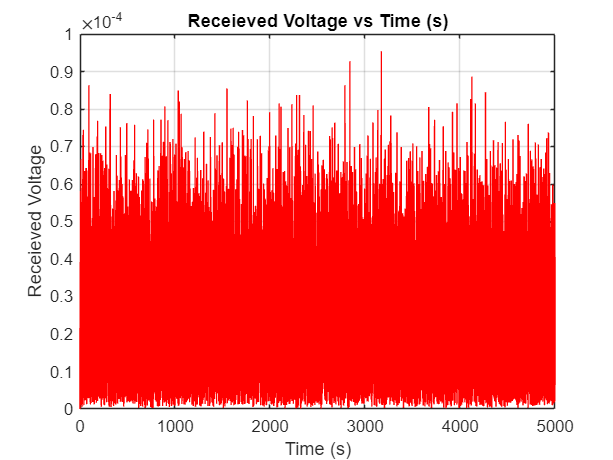


% Plot Voltage vs Time
figure;
plot(time, V, Color = 'r');
xlabel('Time (s)');
ylabel('Receieved Voltage');
title('Receieved Voltage vs Time (s)');
grid on;

% Step 2 -> Normalized

% Normalize Vector
V_norm = V / sigma;

% Find Mean Of Normalized Voltage Vector
V_avg_norm = mean(V_norm);

% Sigma Normalized Parameter
sigma_norm = V_avg_norm / sqrt(pi/2);

% Display Values
disp(['Mean Of Normalized Voltage Vector: ', num2str(V_avg_norm)]);

Mean Of Normalized Voltage Vector: 1.2533


disp(['Normalized Sigma Paramter: ', num2str(sigma_norm)]);

Normalized Sigma Paramter: 1


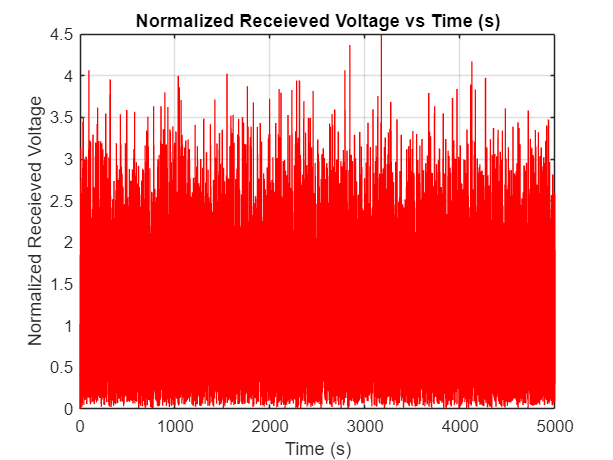


% Plot Normalized Voltage vs Time
figure;
plot(time, V_norm, Color = 'r');
xlabel('Time (s)');
ylabel('Normalized Receieved Voltage');
title('Normalized Receieved Voltage vs Time (s)');
grid on;

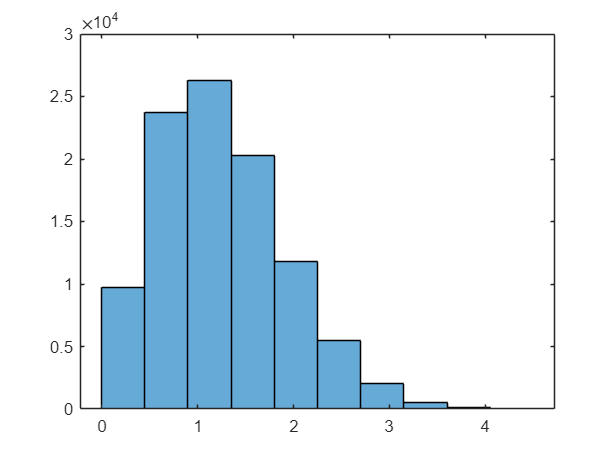

% Step 3

% Calculate Samples In Each Bin & Center Of Each Bin
K = 10;
h = histogram(V_norm, K);

mj = h.Values;
Cj = h.BinEdges(1:end-1) + diff(h.BinEdges)/2;
M = length(V_norm);

% Calculate Delta and Measured pdf
delta = (Cj(end) - Cj(1)) / (K - 1);
measured_pdf = mj ./ (M*delta);

% Display Vectors
disp('Bin Samples (mj):'); disp(mj);

Bin Samples (mj):
        9757       23740       26287       20273       11802        5487        2004         517         119          14



disp('Bin Centers (Cj):'); disp(Cj);

Bin Centers (Cj):
    0.2250    0.6750    1.1250    1.5750    2.0250    2.4750    2.9250    3.3750    3.8250    4.2750



disp(['Bin Length Delta: ', num2str(delta)]);

Bin Length Delta: 0.45


disp('Measured PDF:');

Measured PDF:


disp(measured_pdf);

    0.2168    0.5276    0.5842    0.4505    0.2623    0.1219    0.0445    0.0115    0.0026    0.0003



% Step 4

% Calculate Theoretical pdf
theoretical_pdf = (Cj / sigma_norm^2) .* exp(-Cj.^2 / (2*sigma_norm^2));

% Display Vectors
disp('Theoretical PDF:');

Theoretical PDF:


disp(theoretical_pdf);

    0.2194    0.5375    0.5975    0.4556    0.2606    0.1157    0.0406    0.0113    0.0025    0.0005



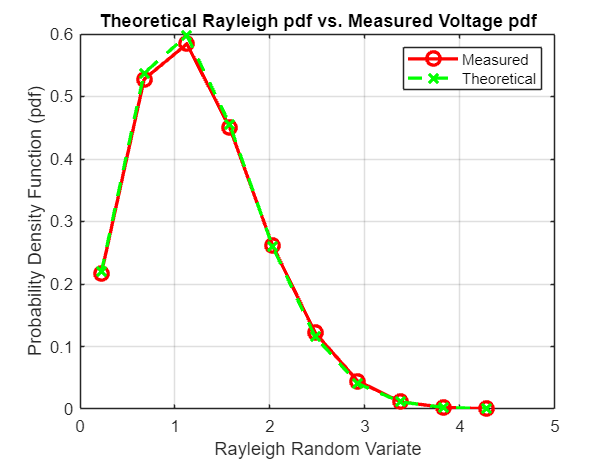

% Step 5 - Test 1

% Plot Measured vs Cj and Theoretical vs Cj
figure;
plot(Cj, measured_pdf, 'r-o', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

plot(Cj, theoretical_pdf, 'g-x', 'LineStyle', '--', 'LineWidth', 2, 'MarkerSize', 8);

xlabel('Rayleigh Random Variate');
ylabel('Probability Density Function (pdf)');
title('Theoretical Rayleigh pdf vs. Measured Voltage pdf');
legend('Measured', 'Theoretical');

grid on;
hold off;

% Step 5 - Test 2

% Calculate All Values
Lj = Cj - (delta / 2); 
Uj = Cj + (delta / 2);                  
pj = exp(-Lj.^2 / (2*sigma_norm^2)) - exp(-Uj.^2 / (2*sigma_norm^2))

pj =     0.0963    0.2367    0.2650    0.2041    0.1183    0.0534    0.0191    0.0055    0.0013    0.0002


Tj = M*pj;   
Z1 = sum(((mj - Tj).^2) ./ Tj);

% Display Vectors
disp(['Bin Length Delta: ', num2str(delta)]);

Bin Length Delta: 0.45


disp('Bin Lower Limit: '); disp(Lj);

Bin Lower Limit: 
   -0.0000    0.4500    0.9000    1.3500    1.8000    2.2500    2.7000    3.1500    3.6000    4.0500



disp('Bin Upper Limit: '); disp(Uj);

Bin Upper Limit: 
    0.4500    0.9000    1.3500    1.8000    2.2500    2.7000    3.1500    3.6000    4.0500    4.5000



disp('Theoretical Probability a Sample Falls in Bin j: '); disp(pj);

Theoretical Probability a Sample Falls in Bin j: 
    0.0963    0.2367    0.2650    0.2041    0.1183    0.0534    0.0191    0.0055    0.0013    0.0002



disp('Theoretical Expected Number of Samples Falls in Bin j: '); disp(Tj);

Theoretical Expected Number of Samples Falls in Bin j: 
   1.0e+04 *

    0.9629    2.3673    2.6496    2.0412    1.1834    0.5344    0.1912    0.0547    0.0126    0.0023



disp(['Chi-Square Statistic: ', num2str(Z1)]);

Chi-Square Statistic: 18.6762



% Does The Test Pass?
Zt = 20.09; 

disp(['Chi-Square Expected Statistic: ', num2str(Zt)]);

Chi-Square Expected Statistic: 20.09



if(Z1 < Zt)
   disp('Test Passed (Z1 < Zt)');
else 
   disp('Test Did Not Pass (Z1 > Zt)');
end 

Test Passed (Z1 < Zt)


% 1% Significance & 
% 8 Degrees (10-1-1) of freedom (K-r-1)
% r = 1